## Word frequency verification

#### Prueba - 6 letters

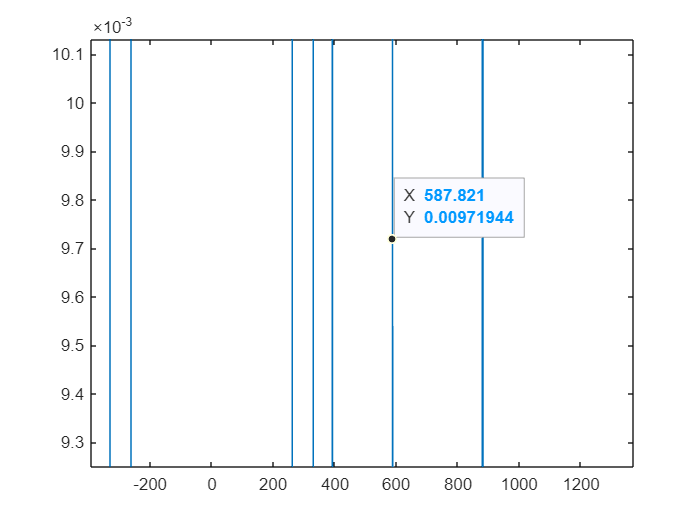

[A,fs] = audioread("prueba.wav") ;
x01 = A(:,1)' ;
f01 = fft(x01)/length(x01);
X01 = fftshift(f01);
omega01 = linspace(-fs/2, fs/2, length(X01));
time = 0:1/fs:length(x01)/fs;
time = time(1:end-1) ;
magnitude01 = abs(X01);
figure
plot(omega01, magnitude01)

xlim([-392 1373])
ylim([0.009249 0.010131])
 
ax = gca;
chart = ax.Children(1);
datatip(chart,879.4,0.009139);
datatip(chart,587.8,0.009719);
datatip(chart,393.3,0.008603);
datatip(chart,329.8,0.008517);
datatip(chart,262.7,0.008023);

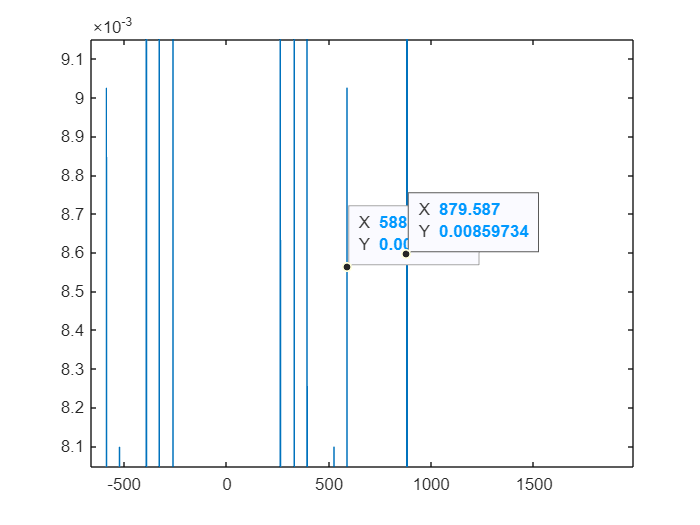

[A,fs] = audioread("AI\NO_VOCALS_117BPM_CMajor_DEM4_pruebamix2 (1).mp3") ;
x01 = A(:,1)' ;
f01 = fft(x01)/length(x01);
X01 = fftshift(f01);
omega01 = linspace(-fs/2, fs/2, length(X01));
time = 0:1/fs:length(x01)/fs;
time = time(1:end-1) ;
magnitude01 = abs(X01);
figure
plot(omega01, magnitude01)

xlim([-172 1432])
ylim([0.008283 0.008951])

% https://www.audiostrip.co.uk/
 
ax2 = gca;
chart2 = ax2.Children(1);
datatip(chart2,879.6,0.008597);
datatip(chart2,588.4,0.008564);
datatip(chart2,393.3,0.007467);
datatip(chart2,330.6,0.006578);
datatip(chart2,262.5,0.009507);

player = audioplayer(A, fs);
play(player);

stop(player);